## Comparison between  Euler method,  ode23 and ode45 solvers 

As the Euler method, both, `ode23 `and` ode45 `belong to the Runge-Kutta method, generally used in numeral analysis for the approximate solutions of ordinary differential equations. 

Euler's method is a simple ODE solver, but it often shows to be a slow solver by presenting a few inherent problems like   only producing exact answers for constant functions and no error estimation. In the graph, one can see that the Euler's method plot differs a lot from the the other plots.

Runge-Kutta algorithms are all *single-step* solvers, since each step only depends on the result of the previous step. `ode45`, `ode23` employ single-step algorithms. 

The main difference between both solvers is that `ode23` is a three-stage third-order Runge-Kutta method and `ode45` is a six-stage fifth-order Runge-Kutta method. As a result`,` `ode 23` can take much larger steps, but the ode45 method does more work per step and  is able to compensate by taking steps of varying size.

For differential equations with smooth solutions, `ode45` is often more accurate than `ode23 or `Euler's method (see the graph). That´s why `ode45` is normally set as the default solver in MATLAB documentation and the results for the solvers may differ`.` 

## Solution with Euler method

figure;

%%% The initial values

tmax = 100;

S = zeros(1, tmax + 1);
I = zeros(1, tmax + 1);
R = zeros(1, tmax + 1);

S(1) = 9999;
I(1) = 1;
R(1) = 0;
N=S(1)+I(1)+R(1);

Incidence = zeros(1, tmax + 1);
Incidence(1) = 0;

Weekly_Incidence = zeros(1, tmax - 6);

%%% The parameters

p=0.1;  % infection probability 
c=5;    % contact rate

beta = p*c/N;
gamma = 0.2;

R_0=beta/gamma;


%%% The Euler method

T = zeros(1,tmax + 1);
T(1) = 0;

for t = 1:tmax
        
    T(t+1) = t;
        
    S(t+1) = S(t) - beta*I(t)*S(t) ;   
    I(t+1) = I(t) + (beta*I(t)*S(t)) - gamma*I(t);    
    R(t+1) = R(t) + gamma*I(t);
    
    Incidence(t+1) = beta*I(t)*S(t);
    
        if t > 5
                
            Weekly_Incidence(t-5) = sum(Incidence(t-5:t+1));
            
        end
end


%%%% The plot

yyaxis left
plot(T, S,  'linestyle','-','color','b','Marker',".", 'LineWidth',0.5,'DisplayName','S(t), susceptible euler'); hold on;
plot(T, I,  'linestyle','-.','color','b','Marker',">", 'LineWidth',0.5,'DisplayName','I(t), infected euler');
plot(T, R,  'linestyle','-','color','b','Marker',"+", 'LineWidth',0.5,'DisplayName','R(t), recovered euler');
ylabel('Population');

yyaxis right 
plot(T, Incidence,'linestyle',':','color','b','Marker',"*",'LineWidth',0.5,'DisplayName','Incidence euler');
plot(T(7:end), Weekly_Incidence,  'linestyle','-','color','b','Marker',".", 'LineWidth',0.5,'DisplayName','Weekly incidence euler')
ylim([1 5000]);
ylabel('Incidence');

title('The SIR Model solved with multiple solvers')
subtitle({['for transmission rate \beta = ',num2str(beta),', recovery rate \gamma = ',num2str(gamma),','], ...
    ['basic reproduction number R_0 = \beta/\gamma = ',num2str(R_0)], ...
    ['and initial conditions S(0) = ',num2str(S(1)),', I(0) = ',num2str(I(1)),', R(0) = ',num2str(R(1))]})


xlabel('time in days');
xlim([0 100]);

hold off;

## Solution with ode23


%%%% The parameters and the initial values

tRange = [0 100];
gamma = 0.2;
beta = 0.00005;
R_0=beta/gamma;
Y0 = [9999; 1; 0];

[tSol,YSol] = ode23(@SIRmodel,tRange,Y0);

%%%% The plot

S = YSol(:,1);
I = YSol(:,2);
R = YSol(:,3);

Incidence = beta*S.*I;

sz = size(tSol);
Weekly_Incidence = zeros(sz(1)-6,sz(2));

for n = 7:sz(1)

    Weekly_Incidence(n-6) = sum(Incidence(n-6:n));
 
end
hold on
yyaxis left
plot(tSol,S, 'linestyle','-','color','r','Marker',".", 'LineWidth',1,'DisplayName','S(t), susceptible ode23'); 
plot(tSol,I, 'linestyle','-.','color','r','Marker',">", 'LineWidth',1,'DisplayName','I(t), infected ode23');
plot(tSol,R, 'linestyle','-','color','r','Marker',"+", 'LineWidth',01,'DisplayName','R(t), recovered ode23');

yyaxis right
plot(tSol,Incidence, 'linestyle',':','color','r','Marker',"*", 'LineWidth',1,'DisplayName','Incidence ode23');
plot(tSol(7:end), Weekly_Incidence,'linestyle','-','color','r','Marker',".", 'LineWidth',1,'DisplayName','Weekly incidence ode23')


subtitle({['for transmission rate \beta = ',num2str(beta),', recovery rate \gamma = ',num2str(gamma),','], ...
    ['basic reproduction number R_0 = \beta/\gamma = ',num2str(R_0)], ...
    ['and initial conditions S(0) = ',num2str(Y0(1)),', I(0) = ',num2str(Y0(2)),', R(0) = ',num2str(Y0(3))]})



## Solution with ode45

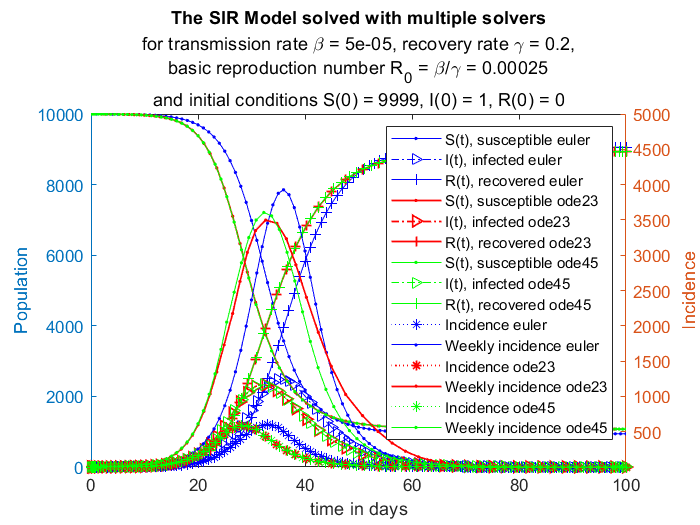


%%%% The parameters and the initial values

tRange = [0 100];
gamma = 0.2;
beta = 0.00005;
R_0=beta/gamma;
Y0 = [9999; 1; 0];

[tSol,YSol] = ode45(@SIRmodel,tRange,Y0);

%%%% The plot

S = YSol(:,1);
I = YSol(:,2);
R = YSol(:,3);

Incidence = beta*S.*I;

sz = size(tSol);
Weekly_Incidence = zeros(sz(1)-6,sz(2));

for n = 7:sz(1)

    Weekly_Incidence(n-6) = sum(Incidence(n-6:n));
 
end
yyaxis left
plot(tSol,S,'linestyle','-','color','g','Marker',".", 'LineWidth',0.5,'DisplayName','S(t), susceptible ode45');
plot(tSol,I,'linestyle','-.','color','g','Marker',">", 'LineWidth',0.5,'DisplayName','I(t), infected ode45');
plot(tSol,R,'linestyle','-','color','g','Marker',"+", 'LineWidth',0.5,'DisplayName','R(t), recovered ode45');

yyaxis right
plot(tSol,Incidence, 'linestyle',':','color','g','Marker',"*",'LineWidth',0.5,'DisplayName','Incidence ode45');
plot(tSol(7:end), Weekly_Incidence,'linestyle','-','color','g','Marker',".", 'LineWidth',0.5,'DisplayName','Weekly incidence ode45')


subtitle({['for transmission rate \beta = ',num2str(beta),', recovery rate \gamma = ',num2str(gamma),','], ...
    ['basic reproduction number R_0 = \beta/\gamma = ',num2str(R_0)], ...
    ['and initial conditions S(0) = ',num2str(Y0(1)),', I(0) = ',num2str(Y0(2)),', R(0) = ',num2str(Y0(3))]})

hold off;
legend ('show')

function dYdt = SIRmodel(~,Y)

    % Extract S, I, and R from input vector Y
    S = Y(1); % susceptible
    I = Y(2); % infected
    R = Y(3); % recovered
    
    % Define the constants beta and gamma
    beta = 0.00005;
    gamma = 0.2;
    
    % Define dSdt, dIdt, dRdt from the ODEs
    dSdt = -beta*S*I;
    dIdt = beta*S*I - gamma*I;
    dRdt = gamma*I;
    
    % Create output column vector dYdt
    dYdt = [dSdt; dIdt; dRdt];
    
end